# Getting Started with Widgets Toolbox - Compatibility Support

## Compatibility Warning

This toolbox is intended to provide compatibility support for MATLAB applications that have been already developed in releases prior to R2020b using traditional (Java-based) figure windows. 

### Migrating Apps to UI Figure Windows

A goal of this toolbox is to provide continuing support for existing apps to be migrated to UI Figure windows (uifigure) with minimal code modifications needed. Migration of existing widgets content is supported for most content starting with MATLAB R2020b. 

Some of the less frequently used content may not be supported for simple placement in uifigure and may require manual modifications or structural changes. The migration is primarily implemented by creating a uifigure equivalent control and passthrough of property information to the new component.

For developing new apps, you should instead begin with uifigure and, if desired, use the new "Widgets Toolbox - MATLAB App Building Components".

## Introduction

Widgets Toolbox (Compatibility Support) continues to support advanced GUI programmers who have developed complex user interfaces using advanced modular building blocks. A widget is a single object that can contain a composition of multiple controls together, along with the related logic. You can also create your own widgets by replicating the pattern used within the existing components in this toolbox.

### Recommendation for migrating apps

It is recommended to begin testing the migration of existing apps to use uifigure. Widgets Toolbox is continuing to be updated to support as much content as possible to smoothly move from traditional MATLAB figure into a uifigure. The majority of Widgets Toolbox content should work when placed into a uifigure instead of a traditional figure.

Some less-frequently used capabilities may remain unsupported. If you find a need for missing capability, it is recommended to report it to MathWorks support to prioritize it for a future release.

## Migrating Widgets Content

In most cases, migrating content into a uifigure is simply a matter of placing the content into the uifigure. (Note that migration requires MATLAB R2020b or later.) Please see the release notes at the end of this document for known limitations.

For example:

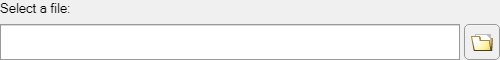

f = uifigure('Name','UI Figure','Position',[100 100 500 60]);
w = uiw.widget.FileSelector('Parent',f);
w.Label = 'Select a file:';
w.LabelLocation = 'top';

### Migrating Complete Apps

For complete apps that inherit the following Widgets Toolbox classes:

- uiw.abstract.AppWindow

- uiw.abstract.SessionManagement

- uiw.abstract.MultiSessionApp

testing the migration simply requires you to provide an input argument to the superclass constructor:

After making this change, you need to review any errors that occur when launching the app. It is possible (maybe even likely) that some other changes may be needed to complete the migration. 

## Creating a Widget (Compatibility support)

To start, we need a figure. Return the figure handle as `f` so we can place the widget.

f = figure

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1257 1207 560 420]
       Units: 'pixels'

  Show all properties


Now we can add a widget to our figure:

w = uiw.widget.FileSelector('Parent',f)

w =   FileSelector with properties:

   Common Widget Properties: (help on this widget)
                        Parent: [1×1 Figure]
                        Enable: 'on'
                      Position: [0 0 1 1]
                         Units: 'normalized'
                       Padding: 0
                       Spacing: 4
                      FontName: 'MS Sans Serif'
                      FontSize: 10
                    FontWeight: 'normal'
               ForegroundColor: [0 0 0]
               BackgroundColor: [0.9400 0.9400 0.9400]
                           Tag: ''

   Common Widget Label Properties:
                         Label: ''
                 LabelLocation: 'left'
                   LabelHeight: 20
                    LabelWidth: 75
                 LabelFontName: 'MS Sans Serif'
                 LabelFontSize: 10
               Label

Position the widget:

w.Units = 'pixels';
w.Position = [10 40 500 25];

We can add a label, and make it wide enough for the text:

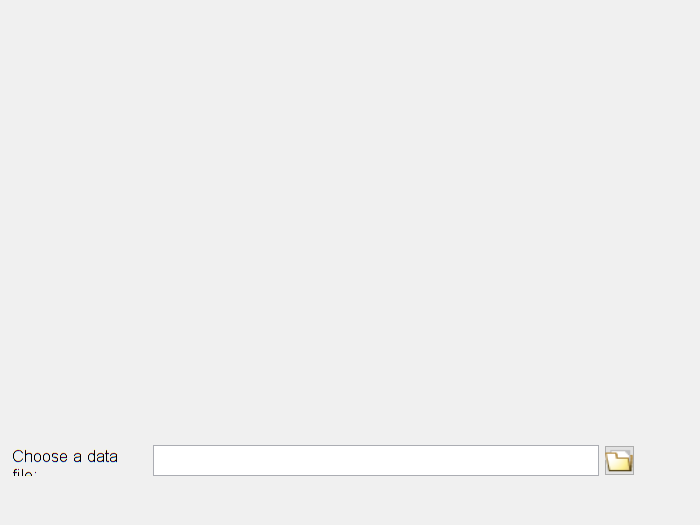

w.Label = 'Choose a data file:';
w.LabelWidth = 110;

The widget should look like this:

By default the widget is configured to look for *.mat files. Configure the widget to find *.m files like this:

w.Pattern = {'*.m;*.mlx','MATLAB Code (*.m, *.mlx)'}

w =   FileSelector with properties:

   Common Widget Properties: (help on this widget)
                        Parent: [1×1 Figure]
                        Enable: 'on'
                      Position: [10 40 500 25]
                         Units: 'pixels'
                       Padding: 0
                       Spacing: 4
                      FontName: 'MS Sans Serif'
                      FontSize: 10
                    FontWeight: 'normal'
               ForegroundColor: [0 0 0]
               BackgroundColor: [0.9400 0.9400 0.9400]
                           Tag: ''

   Common Widget Label Properties:
                         Label: 'Choose a data file:'
                 LabelLocation: 'left'
                   LabelHeight: 20
                    LabelWidth: 110
                 LabelFontName: 'MS Sans Serif'
                 LabelFontSize: 10

And a callback. The callback function specified using a function handle.

For now, the callback will just display the eventdata in the command window. In your actual implementation, replace the `disp` below with the name of your own callback function. 

w.Callback = @(h,e)disp(e);

Now interact with the widget. If you select a file, you will see the result in the command window.

### Special Note: Using Function Handles with Graphics Callbacks

Graphics callbacks always provide two input arguments that may be used in your callback function. The first (`h` above) is always the object that was interacted upon, and the second (`e` above) is always the event data about the interaction. 

To create the function handle (right of the `=` above), you always need to define the two default arguments `@(h,e)` before the callback function name. After the function name, you may choose whether or not these inputs get passed in to the function. 

You may pass additional arguments into the callback as well. Those additional inputs must be defined in the current workspace when you create the function handle.

If your callback is calling the method of an object, you need to use the object notation that looks like either of these:

% @(h,e)obj.methodname(e);
% @(h,e)methodname(obj,e);

## Using Widgets with GUI Layout Toolbox

[GUI Layout Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/47982-gui-layout-toolbox) provides a framework to manage positioning and resizing of complex user interface layouts. It is very useful when positioning widgets.

After installing [GUI Layout Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/47982-gui-layout-toolbox), you can position widgets like this:

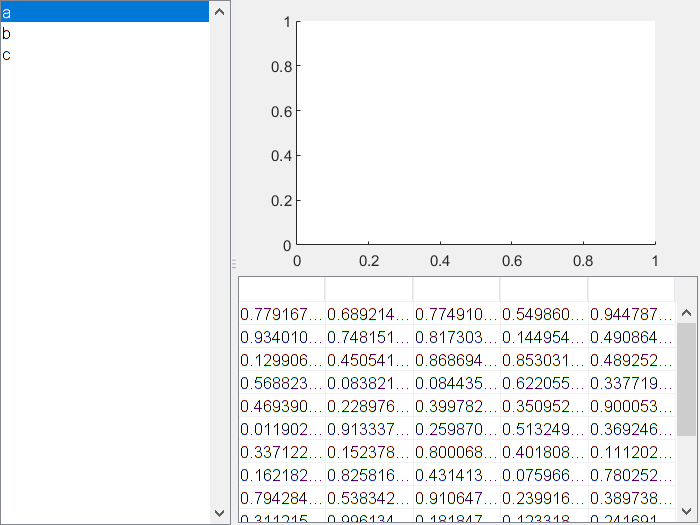

rightVBox =     VBox


f = figure;

% A horizontal flex layout
mainHBox = uix.HBoxFlex('Parent',f);

% On the horizontal, place a widget and a fixed vertical layout
list = uiw.widget.List('Parent',mainHBox,'Items',{'a','b','c'});
rightVBox = uix.VBox('Parent',mainHBox);

% On the right vertical, place an axes and a table. (Axes should be placed
% inside a container in case legend or colorbar is added.)
axesContainer = uicontainer('Parent',rightVBox);
rightAxes = axes('Parent',axesContainer);
rightTable = uiw.widget.Table('Parent',rightVBox,'Data',rand(15,5));

% Set the layout size
mainHBox.Widths = [-1 -2]; %scaled width for both, wider on the right
rightVBox.Heights = [-1 200] %fixed pixel height for lower table

## Release Notes

### Version 1.4.0 (November 12, 2020)

The majority of widgets are compatible with uifigure in R2020b and later. 

#### Known Limitations

There are known limitations that can not currently be migrated to uifigure. These include:

Dialogs

- Custom dialogs are not currently supported to be launched inside of a uifigure, and must open in a new figure window.  Dialogs from the uiw.dialog.* package will still open in a traditional figure window. These dialogs include Widgets dialogs TableSelectionDialog, AboutDialog, SearchListDialog, and any user-created dialogs that inherit uiw.abstract.BaseDialog. (Note that only single window apps are currently supported by MATLAB Web App Server.)

The Table widget is limited to the functionality available in the MATLAB uitable when used in a uifigure. 

- Mouse and Keyboard callbacks are unavailable.

- Drag and drop is unavailable.

- Unsupported column formats include: 'longchar', 'popuplist',, 'imageicon', 'custom'.  Formats 'date' and 'color' have basic behavior and are read-only.

- Column width controls and choice of resize behavior are limited.

- Programmatically sorting a column is unavailable.

The Tree widget is limited to the functionality available in the MATLAB uitree when used in a uifigure.

- CheckboxTree is not yet supported.

- Mouse and keyboard callbacks are unavailable.

- Drag and drop is unavailable.

Other widget incompatibilities:

- HTML entered into a component for styling text is not supported

- Slider will appear like a uislider, not like a traditional uicontrol slider

- EditablePopup lacks keyboard callbacks

 There may be additional limitations not covered here.

### Version 1.3.330 (April 24, 2019)

Bugfixes:

- Bugfixes to Table and Tree mouse events: ButtonDownFcn being called multiple times, selecting multiple cells with CTRL was bringing up context menu, expanding tree node was changing selection.Tree no longer errors when using string types.

- Fixes to session/app superclasses: SessionManagement and Preferences class bugs, other issues with Open and Open Recent files. Removed warning in MultiSessionApp class.

- Added various utilities (not fully documented) and mixin class DisplayNonScalarObjectAsTable

- Add ListSelector widget and dialog

- Fix to AssignPVPairs mixin in case an output is requested but no inputs present

- Converted demos to live script (mlx) format.

- Added function signatures help for widgets and dialogs.

### Version 1.2.308 (January 29, 2019)

Bugfixes:

- Bugfixes to Table for editing with numeric data format and for color column format

### Version 1.2.305 (January 15, 2019)

Bugfixes:

- Several small bugfixes with new string type support (including failure to work in R2017a)

- Fixed issue in SessionManagement class causing two notifications on creating a new session.

- MultiSessionApp superclass is still in development, but is relatively stable now. It is still in testing phase and is subject to change.

- Fixed bug with font on CheckboxTree

- Fixed bug with column headers on Table not scrolling to the right properly

### Version 1.2.289 (November 14, 2018)

Bugfixes:

- Creating a TreeNode hierarchy before attaching to a Tree was not rendering all descendants. (Creating an unparented hierarchy of nodes before parenting them to the root is faster.)

- Tree and JavaControl superclass: Mouse clicks were not always registering correctly, and in some situations incorrectly bringing up context menu and changing selection. 

- Table RowHeight property was not being applied.

- Internal changes made to SingleSessionApp and SessionManagement, and prototype for MultiSessionApp superclass in development. (The changes should not affect any existing usage of apps inheriting SingleSessionApp.)

- Bugfixes to Logger class.

- Performance improvement to AssignPVPairs superclass.

- Support string scalar datatype for some widgets

### Version 1.1.257 (October 15, 2018)

Add application superclasses and demos

- uiw.abstract.AppWindow, uiw.abstract.SingleSessionApp, and related classes

- demoApp and +demoAppPkg folder of content to show a full app with session management

Add Logging capabilities, useful for large or deployed applications

- Logger, LogMessage, and HasLogger classes added

- New demo: demoLog.m

Bugfixes

- Widgets: Label, Popup, Slider, Table

- Application of BackgroundColor/ForegroundColor on all widgets

New Components

- Widgets: ImageSelector, ProgressBar

- Dialogs: About, SearchList, TableSelection

Other Changes

- FixedText widget renamed to Text to avoid confusion. (Existing code referencing FixedText should still work.)

### Version 1.0.245 (September 21, 2018)

Minor Changes

- Toolstrip renamed Toolbar to accurately reflect its capability. Toolbar also now enables toggling group visibility to show/hide sections. (Existing code referencing Toolstrip should still work.)

- Added Contents.m file to allow toolbox and version number to be registered with "ver" command in MATLAB.

### Version 1.0.0 (March 8, 2018)

Initial Release.

© 2018-2020 The MathWorks, Inc.